## Random Forest Hyperparameter Search

This script performs a detailed search for the final model's hyperparameters.

### Initialise

% CLear all, load the dataset
clear
clc
clf
close all
% loads the letter dataset 
% 
load letterDatasetClass.mat
letterDataset = letterDatasetStandardisedReducedFeatures;
disp(letterDataset);

  LetterDatasetClass with properties:

           datasetFilePath: "Dataset/letter-recognition.csv"
         testSetProportion: 0.2000
                randomSeed: 1
                targetName: {'TargetAscii'}
              featureNames: {1×12 cell}
          validClassValues: [26×1 table]
    datasetContentsAsTable: [20000×13 table]
                trainTable: [16000×13 table]
                 testTable: [4000×13 table]
            isStandardised: 1
          isRemovedFeature: 1



### Check Random Forest Analysis Code Works

hyperParameters = RFHyperparameters.getHyperQuickInstance();

rfHyperparameters =   RFHyperparameters with properties:

      features: [2 4]
         trees: 25
         folds: [2 3]
    randomSeed: 122


rfClass = RandomForestClass(hyperParameters);
rfClass.debug = true;
results = rfClass.performAnalysis(letterDataset, "RFQuickTest.csv");

Starting Random Forest analysis...
Misclassified 178 entries out of 3200. 5.5625 pct	Training loss: 0.01. Test Loss: 0.09 Oob Error: 0.18	Precision: 0.9439 Recall: 0.9441 Accuracy: 0.9444 F1: 0.9440
	numTree 25 numFeature 2 trainErr 0.0104 testErr 0.0870 oobErr 0.1843 fold 1  of 2 predictTime 0.6200	Samples: T I D N G
Misclassified 168 entries out of 3200. 5.2500 pct	Training loss: 0.01. Test Loss: 0.08 Oob Error: 0.18	Precision: 0.9472 Recall: 0.9478 Accuracy: 0.9475 F1: 0.9475
	numTree 25 numFeature 2 trainErr 0.0102 testErr 0.0846 oobErr 0.1837 fold 2  of 2 predictTime 0.4600	Samples: T I D N A
Misclassified 161 entries out of 3200. 5.0312 pct	Training loss: 0.01. Test Loss: 0.08 Oob Error: 0.18	Precision: 0.9494 Recall: 0.9500 Accuracy: 0.9497 F1: 0.9497
	numTree 25 numFeature 2 trainErr 0.0104 testErr 0.0838 oobErr 0.1829 fold 1  of 3 predictTime 0.3700	Samples: T I G A M
Misclassified 145 entries out of 3200. 4.5312 pct	Training loss: 0.01. Test Loss: 0.08 Oob Error: 0.18	Precisi

disp(results.resultsTable);

    feature    tree    folds    randomTreebagSeed    avgTrainLoss    avgTestLoss    avgOobLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    _______    ____    _____    _________________    ____________    ___________    __________    ___________    ____________    _________    ______    __________    ___________    ______________

       2        25       2              1               0.0103         0.0858          0.184        0.9459          0.9456         

### Hyperparameter Optimization Search

hyperParameters = RFHyperparameters.getHyperDefaultInstance();
rfClass = RandomForestClass(hyperParameters);
rfClass.debug = false;
results = rfClass.performAnalysis(letterDataset, "RFDefaultTest.csv");

Starting Random Forest analysis...


results = RFResults.getInstanceFromCsvResults("RFDefaultTest.csv");
disp(results.resultsTable);

    feature    tree    folds    randomTreebagSeed    avgTrainLoss    avgTestLoss    avgOobLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    _______    ____    _____    _________________    ____________    ___________    __________    ___________    ____________    _________    ______    __________    ___________    ______________

       2        50       2              1               0.0055         0.0679         0.1257        0.9528          0.9523        0

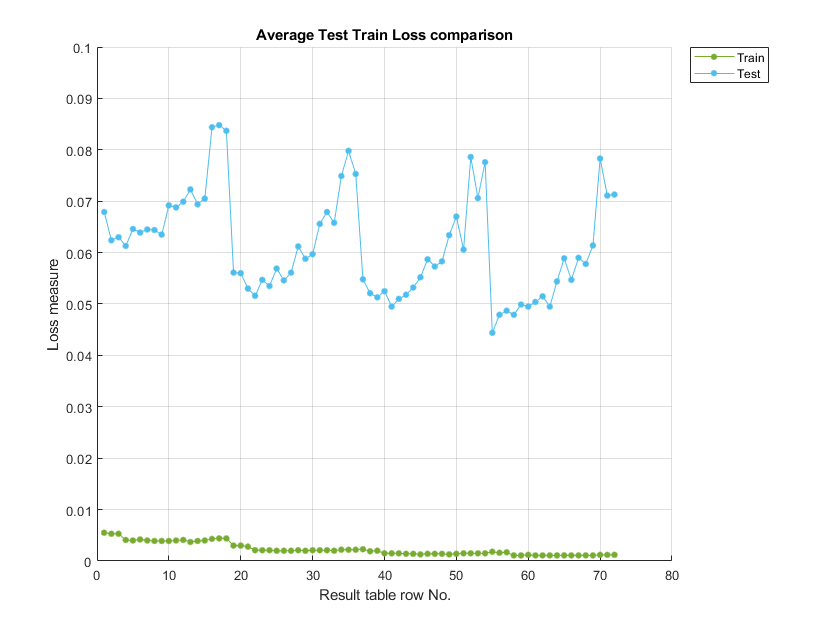

PlotUtil.plotLossTestTrainComparisonWithYMax(results.resultsTable, "Average Test Train Loss comparison", 0.1);

Rows 58, 41 and 22 look interesting: smallest loss in their group. The results for these rows is shown below:

disp(results.resultsTable([58,41,22],:));

    feature    tree    folds    randomTreebagSeed    avgTrainLoss    avgTestLoss    avgOobLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    _______    ____    _____    _________________    ____________    ___________    __________    ___________    ____________    _________    ______    __________    ___________    ______________

       4       200       2             58               0.0011         0.0479         0.0665        0.9583          0.9579        0

As stated by [1] and [2], 100 trees is the minimum acceptable, more trees gives slightly better results, but takes considerably longer.

[3] report that the number of folds has little effect on prediction using decision trees, in fact they report that the only reason they use two folds is that using one fold is not a reccomended statistical practise.

The number of features that perform best are 4.

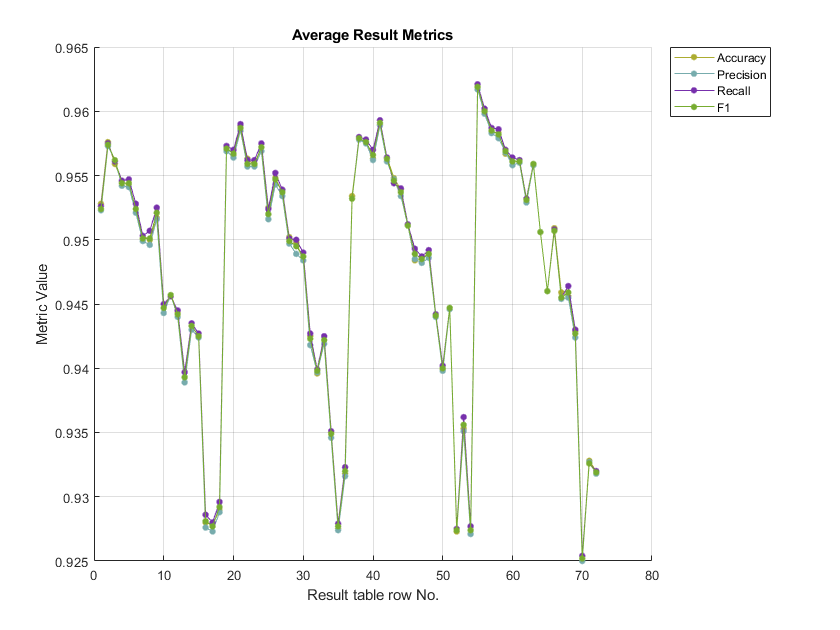

PlotUtil.plotMetrics(results.resultsTable, "Average Result Metrics");

Rows 17, 35, 54, 70 look interesting in terms of performance, their metrics are shown below:

disp(results.resultsTable([58,41,22],:));

    feature    tree    folds    randomTreebagSeed    avgTrainLoss    avgTestLoss    avgOobLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    _______    ____    _____    _________________    ____________    ___________    __________    ___________    ____________    _________    ______    __________    ___________    ______________

       4       200       2             58               0.0011         0.0479         0.0665        0.9583          0.9579        0

- Accuracy, precision and recall move together. 

- The best number of features is again 4. 

- The number of folds does not seem to have much effect

- 200 trees versus 100 for 2% better performance is acceptable

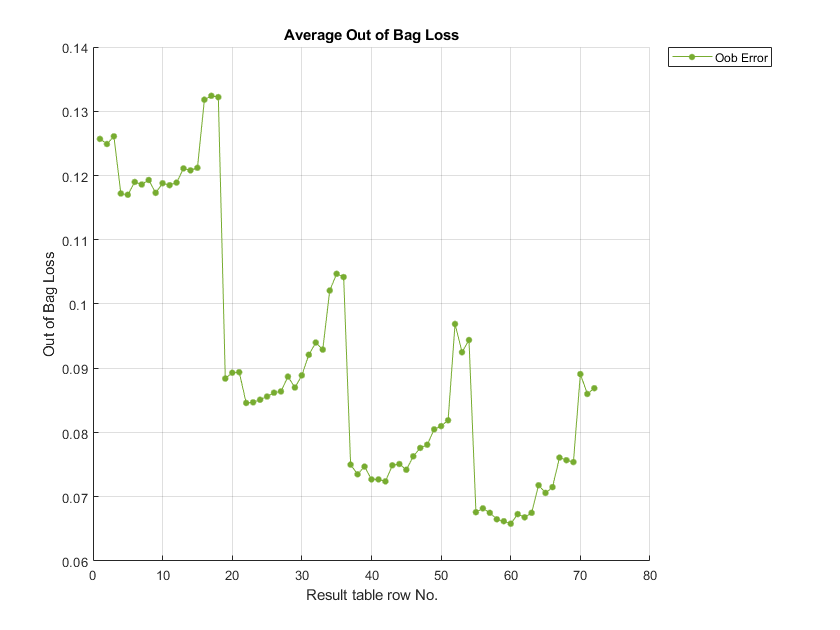


PlotUtil.plotOob(results.resultsTable, "Average Out of Bag Loss");

Rows 40, 60 look interesting

disp(results.resultsTable([20, 40,60],:));

    feature    tree    folds    randomTreebagSeed    avgTrainLoss    avgTestLoss    avgOobLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    _______    ____    _____    _________________    ____________    ___________    __________    ___________    ____________    _________    ______    __________    ___________    ______________

       2       100       3             20                0.003          0.056         0.0893        0.9566          0.9564         

The out of bag loss and time are the two considerations: 2% less loss for approximately twice the time. 

The prediction time ranges between like the candidate to select for the number of trees.

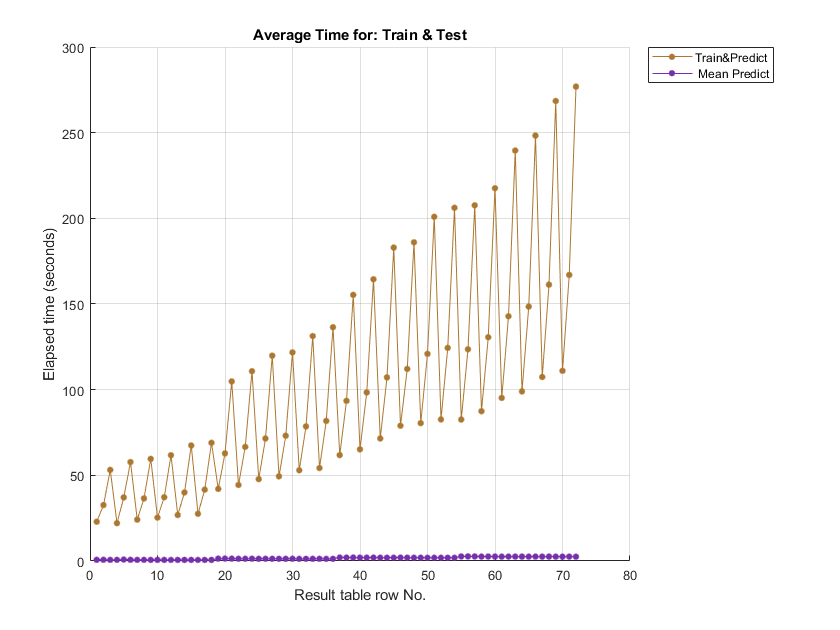

PlotUtil.plotTime(results.resultsTable, "Average Time for: Train & Test")

A repeated pattern is apparent, with low, medium and high times. Which hyperparameter is found by looking at the details below:

disp(results.resultsTable([22,23,24],:));

    feature    tree    folds    randomTreebagSeed    avgTrainLoss    avgTestLoss    avgOobLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    _______    ____    _____    _________________    ____________    ___________    __________    ___________    ____________    _________    ______    __________    ___________    ______________

       4       100       2             22               0.0021         0.0516         0.0846        0.9563          0.9557        0

The results show that the number of folds was the predominant factor for the time difference. The number of folds affects the time taken to grow the tree. The longest time to train the ensemble is under 6 minutes, which is acceptable.

In conclusion the hyperparameters to use for the final model are: 200 trees, 4 features, 60 as the random seed.

### Train TreeBagger Model

rng(1);
model = TreeBagger(50, letterDataset.trainTable, "TargetAscii", ...
  "OOBPrediction", "On", ...
  "OOBPredictorImportance", "On", ...
  'PredictorSelection','curvature', ...
  "Method", "classification")

Error using cell/setdiff>cellsetdiffR2012a (line 291)
Input A of class cell and input B of class cell must be cell arrays of character vectors, unless one is a character vector.

Error in cell/setdiff (line 129)
        [varargout{1:nlhs}] = cellsetdiffR2012a(varargin{1:2},logical(flaginds(1:3)));

Error in 

### Plot out-of-bag error / number of trees

figure;
oobErrorBaggedEnsemble = oobError(model);
plot(oobErrorBaggedEnsemble)
xlabel 'Number of grown trees';
ylabel 'Out-of-bag classification error';

% plot predictor importances
imp = model.OOBPermutedPredictorDeltaError;

figure;
bar(imp);
title('Curvature Test');
ylabel('Predictor importance estimates');
xlabel('Predictors');
h = gca;
h.XTickLabel = model.PredictorNames;
h.XTickLabelRotation = 45;
h.TickLabelInterpreter = 'none';

### Notes

TreeBagger has several properties of interest:

- `NumPredictorsToSample: number of features to randomly select for each tree, default sqrt(num classes)`

- `NumTrees: the number of trees in the forest`

- `Prior: prior distribution of the classes, this is set to the empirical distribution of the entire training dataset classes`

`Number of trees in the ensemble: Khoshgoftaar (2007) a default value of 100 for trees is good.`

`Braiman (2001): more trees will give better results without overfitting on the validation set.`

`Number of random features for splitting at each step: Khoshgoftarr (2007) (log2 * numFeatures + 1). Matlab uses sqrt(numFeatures)`

### `References`

`[1] Breiman, L., Adele Cutler, `[Random forests - classification description (berkeley.edu)](https://www.stat.berkeley.edu/~breiman/RandomForests/cc_home.htm)

[2] T. M. Khoshgoftaar, M. Golawala, and J. V. Hulse, “An Empirical Study of Learning from Imbalanced Data Using Random Forest,” 

[3] P. W. Frey and D. J. Slate, “Letter recognition using Holland-style adaptive classifiers,” *Mach. Learn.*, vol. 6, no. 2, pp. 161–182, Mar. 1991, doi: 10.1007/BF00114162.